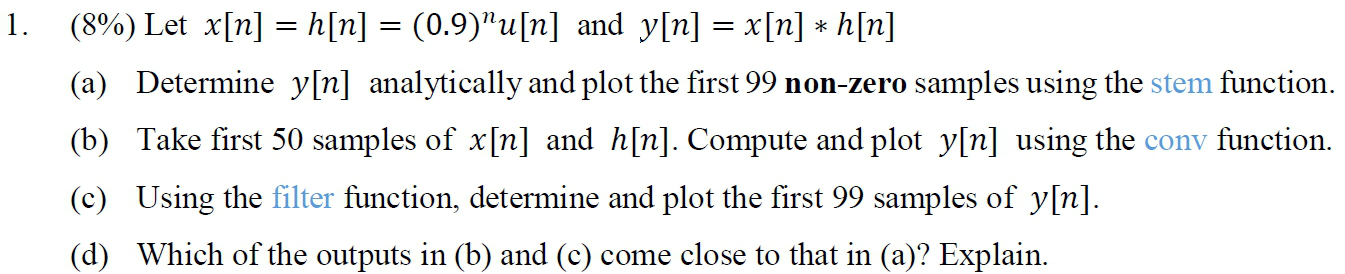

(a)  by defination of convolution , we have


$$\begin{array}{l}
y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack *h\left\lbrack n\right\rbrack =y\left\lbrack n\right\rbrack =\sum_{l=-\infty }^{+\infty } x\left\lbrack l\right\rbrack h\left\lbrack n-l\right\rbrack =\sum_{l=-\infty }^{+\infty } {\left(0\ldotp 9\right)}^l u\left\lbrack l\right\rbrack {\left(0\ldotp 9\right)}^{n-l} u\left\lbrack n-l\right\rbrack \\
={\left(0\ldotp 9\right)}^n \cdot \sum_{l=-\infty }^{+\infty } u\left\lbrack l\right\rbrack u\left\lbrack n-l\right\rbrack ={\left(n+1\right)\cdot \left(0\ldotp 9\right)}^n u\left\lbrack n\right\rbrack 
\end{array}$$


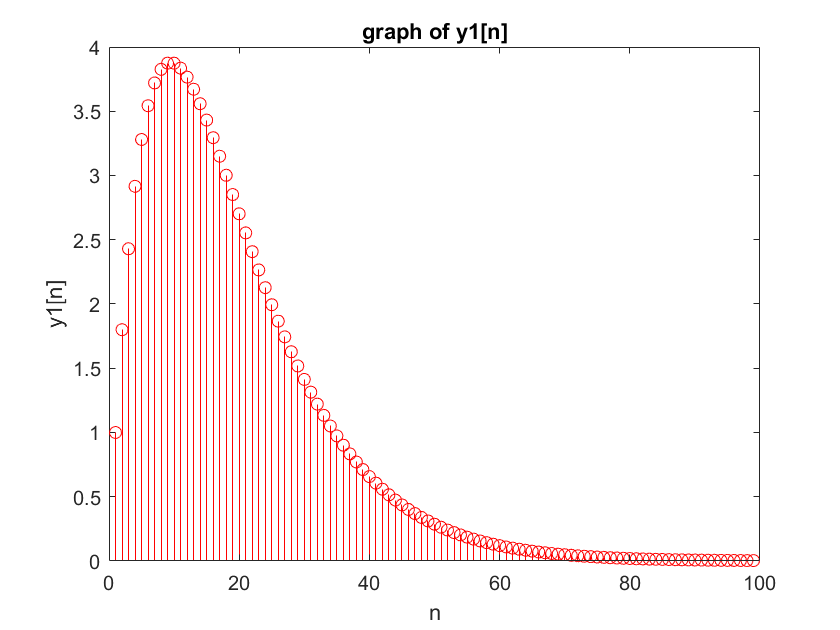

n1 = 0:98;
yn1=(n1+1).*0.9.^n1; % analytic equation derived above
stem(yn1,'r');
title('graph of y1[n]'); xlabel('n'); ylabel('y1[n]');

(b)  'conv(u,v)' would ouput data with `length(u)+length(v)-1``=``50*2-1=99`` points`

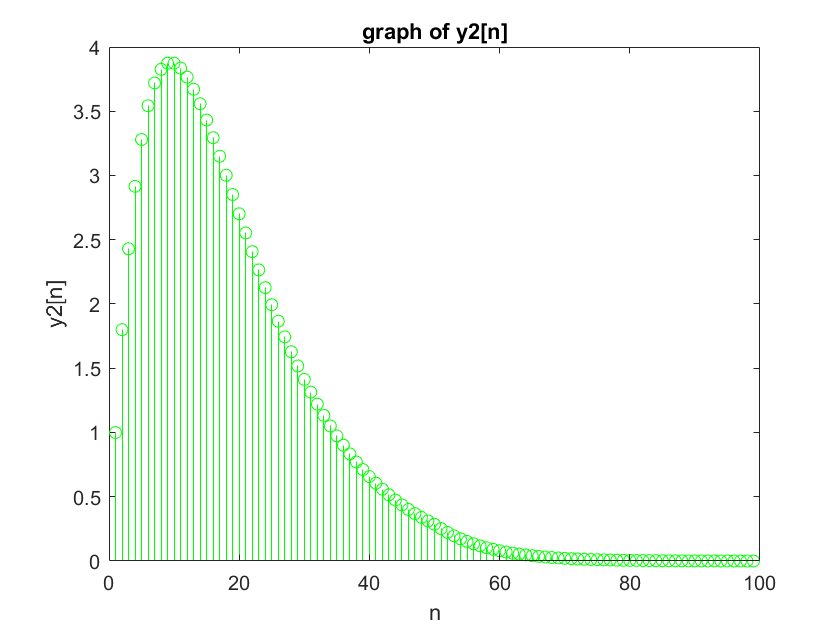

n2 = 0:49; % first 50 samples
xn2 = (0.9).^n2;  hn2 = (0.9).^n2;
yn2= conv(xn2,hn2);
stem(yn2,'g');
title('graph of y2[n]'); xlabel('n'); ylabel('y2[n]');

(c)  '`filter(b,a,x)'` returns the filtered data as **a vector of the same size as **`x``. So let`` length(xn3)=99``.`

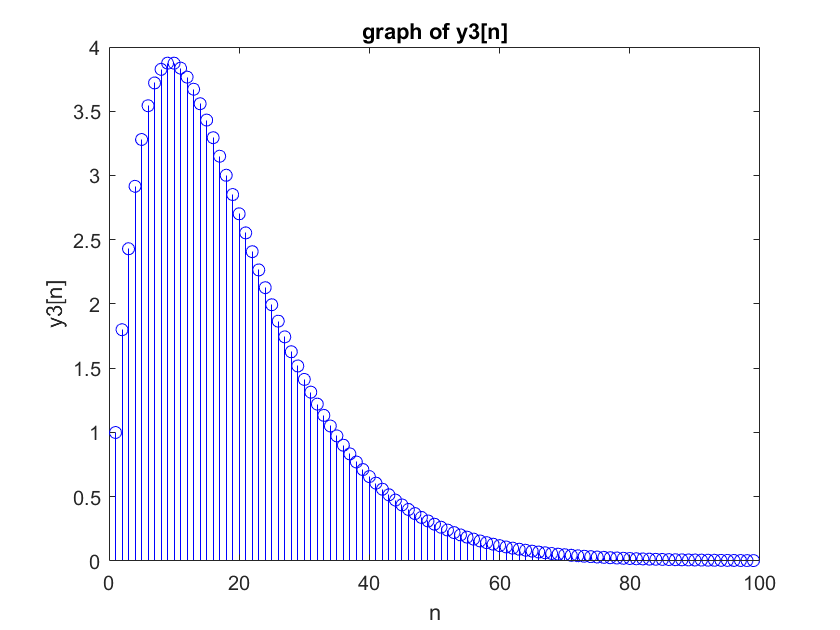

n3 = 0:98; % let length(xn3)=99 to make sure the output of filter is alsa 99 points 
xn3 = (0.9).^n3;  hn3 = (0.9).^n3;
yn3 = filter(hn3,1,xn3);
stem(yn3,'b');
title('graph of y3[n]'); xlabel('n'); ylabel('y3[n]');

(d) check if each element in yn2/ yn3 are the same as yn1 

same_yn1yn2 = length(round(yn1,4)==round(yn2,4));    %50 points are same
same_yn1yn3 = length(round(yn1,4)==round(yn3,4));    %99 points are same

Because  same_yn1yn3  >  same_yn1yn2 (看到小數點後4位時yn3較接近yn1) , so yn3 ( output in (c) )come  closer to yn1 (雖然兩者在stem plot 出的圖形中與yn1都幾乎相同，差別只在小數點下好幾位)

clear all;

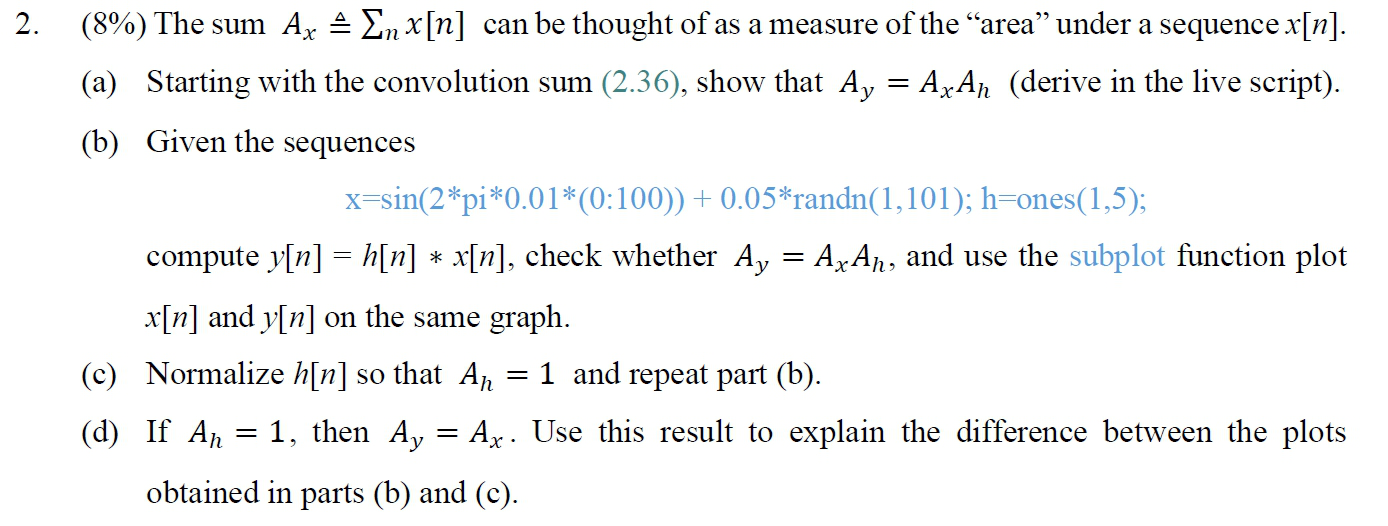

(a) By the difination of convolution sum : $y\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{+\infty } x\left\lbrack k\right\rbrack h\left\lbrack n-k\right\rbrack$.  We have $A_y =\sum_{n=-\infty }^{+\infty } y\left\lbrack n\right\rbrack =\sum_{n=-\infty }^{+\infty } \sum_{l=-\infty }^{+\infty } x\left\lbrack l\right\rbrack h\left\lbrack n-l\right\rbrack =\sum_{l=-\infty }^{+\infty } x\left\lbrack l\right\rbrack \cdot \sum_{n=-\infty }^{+\infty } h\left\lbrack n-l\right\rbrack =A_x {\cdot A}_h$

($\sum_{l=-\infty }^{+\infty } x\left\lbrack l\right\rbrack$=$A_x$ and $\sum_{n=-\infty }^{+\infty } h\left\lbrack n-l\right\rbrack$=${\cdot A}_h$)

(b) 

xn = sin(2*pi*0.01*(0:100)) + 0.05*randn(1,101); hn = ones(1,5);
yn = conv(xn,hn);  

Ax = sum(xn) ; Ah = sum(hn) ; Ay = sum(yn); % use sum do get area 
fprintf('area of Ay : %.4f\n', Ay); %check

area of Ay : 3.2872


fprintf('area of Ay cal = Ax*Ah : %.4f\n', Ax*Ah); %check

area of Ay cal = Ax*Ah : 3.2872


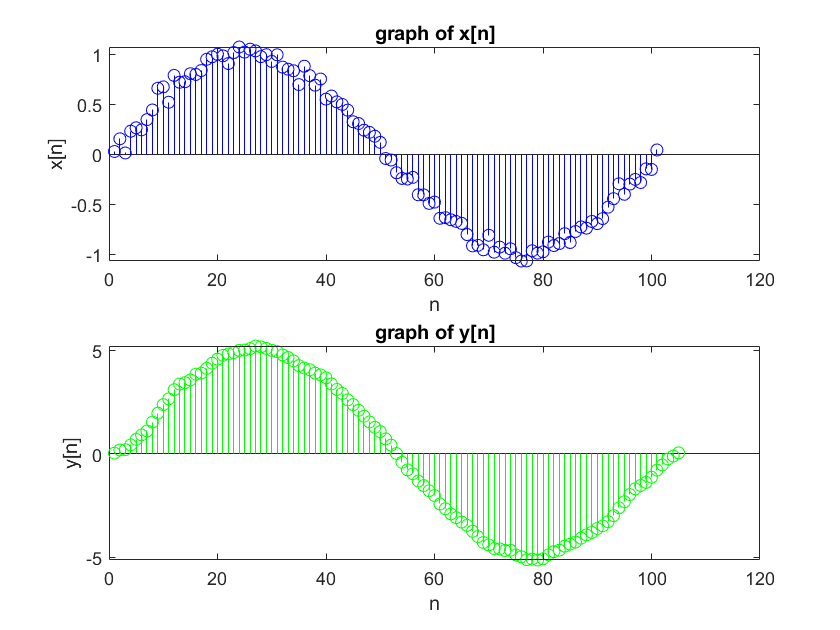


subplot(2,1,1);
stem(xn,'b');
title('graph of x[n]'); xlabel('n'); ylabel('x[n]');


subplot(2,1,2); 
stem(yn,'g');
title('graph of y[n]'); xlabel('n'); ylabel('y[n]');

 實際檢查(計算)Ay約等於Ax*Ah (同樣的若是看到小數點後很多位，可能會有極小差異) 

(c) By defination , Ah = “area” under the sequence h[n] = 5 ; so to normalize , let hn' = 1/5 hn 

new_hn = 0.2*hn; % sum(new_hn)=1;
new_yn = conv(xn,new_hn);  

new_Ah = sum(new_hn); new_Ay = sum(new_yn); % use sum do get area 
fprintf('area of new Ay : %.4f\n', new_Ay); %check

area of new Ay : 0.6574


fprintf('area of new Ay cal = Ax*Ah : %.4f\n', Ax*new_Ah); %check

area of new Ay cal = Ax*Ah : 0.6574


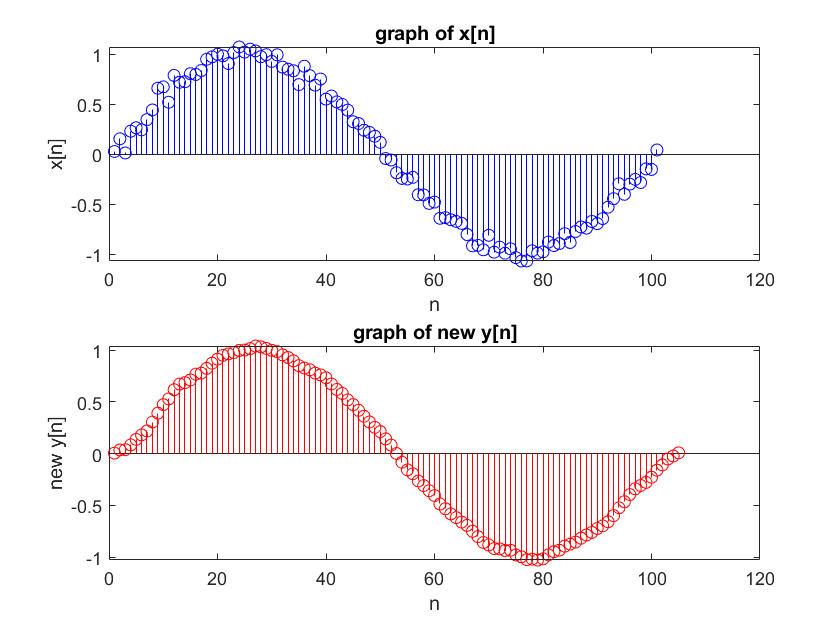


figure;
subplot(2,1,1);
stem(xn,'b');
title('graph of x[n]'); xlabel('n'); ylabel('x[n]');

subplot(2,1,2); 
stem(new_yn,'r');
title('graph of new y[n]'); xlabel('n'); ylabel('new y[n]');

 實際檢查(計算)new_Ay也約等於Ax*new_Ah 

(d)

by the formula derived from part(a) :  Ay=AxAh , so for

(b) Ay=AxAh=Ax*5 (由圖形可看出yn大約是xn的5倍sacling)

(c)new_Ay=Ax*new_Ah=Ax*1=Ax (由圖形可看出new_yn大至上與xn相同，

意即 :  if Ah=1 ,then Ay=Ax ) 

結論 :(b)、(c)部分由於xn相同但hn差了5倍，因此plot出來的yn也差了5倍(高度/面積) 

clear all;

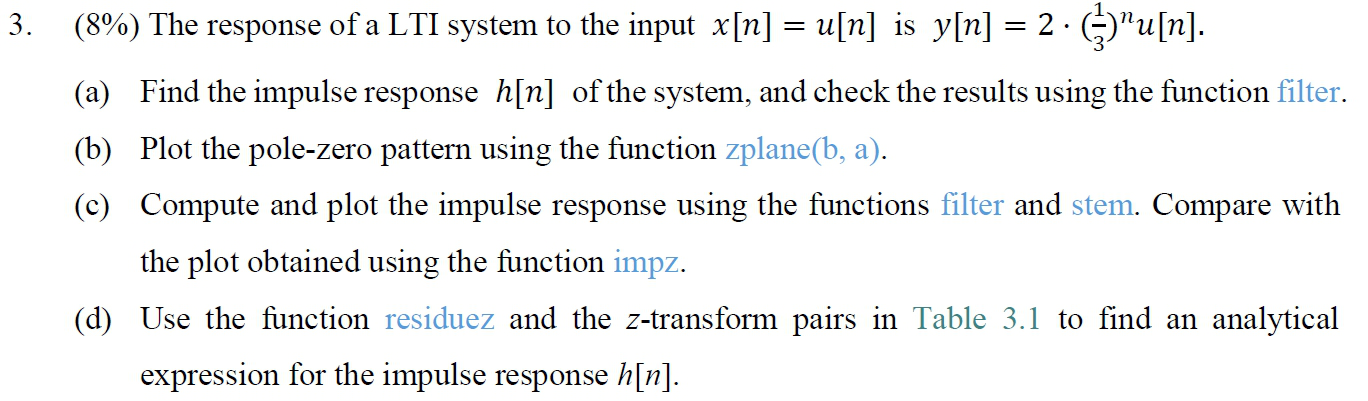

(a)   because for LTI system x[n]-x[n-1]=u[n]-u[n-1]=$\delta \left\lbrack n\right\rbrack \;$, so impluse response h[n]=y[n]-y[n-1]  ,

    [ or just do Z trasform and find H(Z)=$\frac{Y\left(Z\right)}{X\left(X\right)}=$$\frac{2-2z^{-1} }{1-\frac{1}{3}z^{-1} }$$=6+\frac{4}{1-\frac{1}{3}z^{-1} }$ , then apply inverse Z transform (Table 3.1) ]

  use either method , we can get h[n] = $2{\left(\frac{1}{3}\right)}^n u\left\lbrack n\right\rbrack$-$2{\left(\frac{1}{3}\right)}^{n-1} u\left\lbrack n-1\right\rbrack$ = 6$\delta \left\lbrack n\right\rbrack$$-4{\left(\frac{1}{3}\right)}^n u\left\lbrack n\right\rbrack$

which is  2  for n=0 , and $-4{\left(\frac{1}{3}\right)}^n$ for n$\ge 1$ . Now choose the first 20 samples

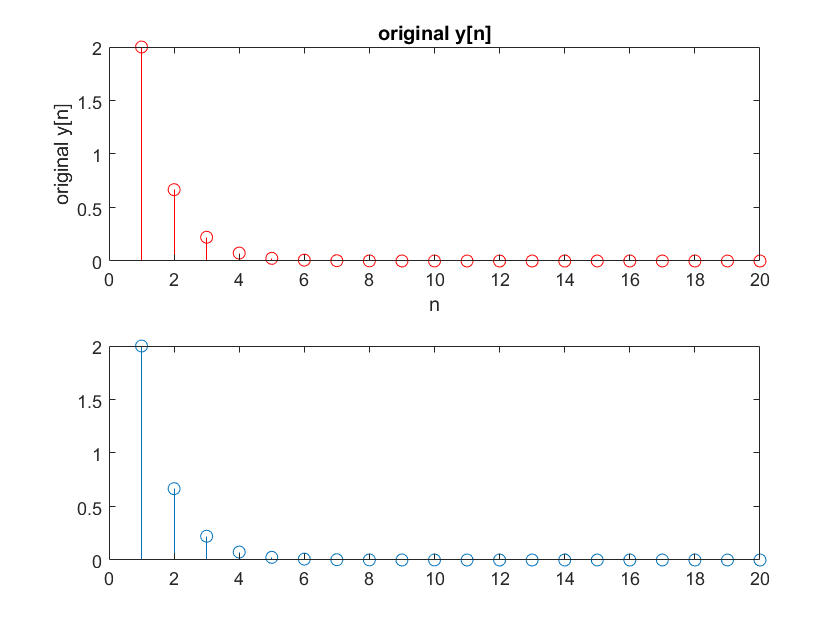

n= 0:19; hn=-4.*(1/3).^n; hn(1)=2; % set h[n]
xn = ones(1,20);  % set x[n] 
yn = 2.*(1/3).^n ; % original y[n]
yn_cal = filter(xn,1,hn); % use filter to do convolution


figure;
subplot(2,1,1);
stem(yn, 'r');
title('original y[n]'); xlabel('n'); ylabel('original y[n]');
subplot(2,1,2);
stem(yn_cal, 'b');
title('calculated y[n]'); xlabel('n'); ylabel('calculated y[n]');
stem(yn);

由得到的兩張圖形(yn yn_cal)相同可以知道計算得出的hn無誤，因此用filter做完convolution之後才會與理論上有相同的yn

(b) from (a) H(Z)$=$$\frac{2-2z^{-1} }{1-\frac{1}{3}z^{-1} }$ , we get b = [2 -2] ,a = [1 -1/3]

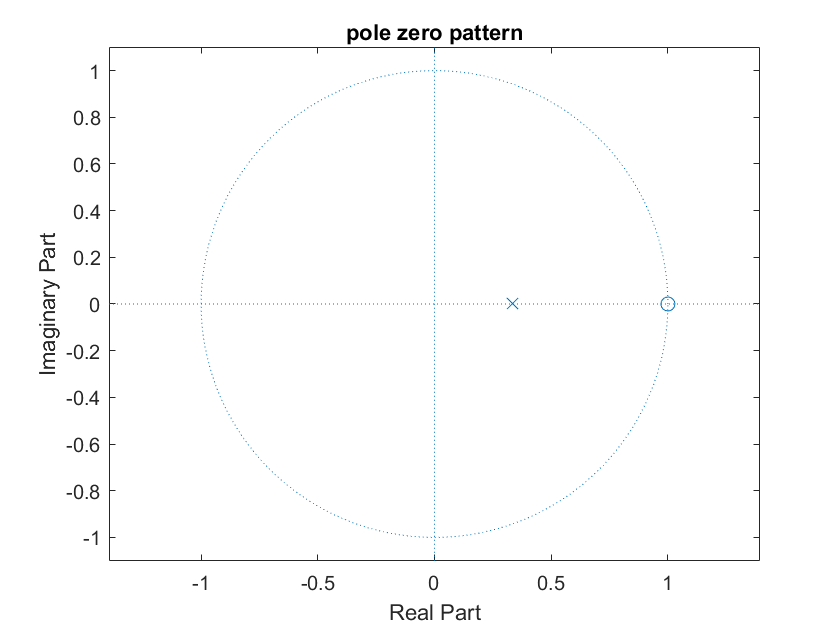

b = [2 -2];  a=[1 -1/3];
figure;
zplane(b,a);
title('pole zero pattern');

由圖形(或H(Z))可以看出 pole為 z  = 1/3 、 zero為 z = 1   

(c) impluse rsponse : input =$\delta \left\lbrack n\right\rbrack \;$, output = h[n] 

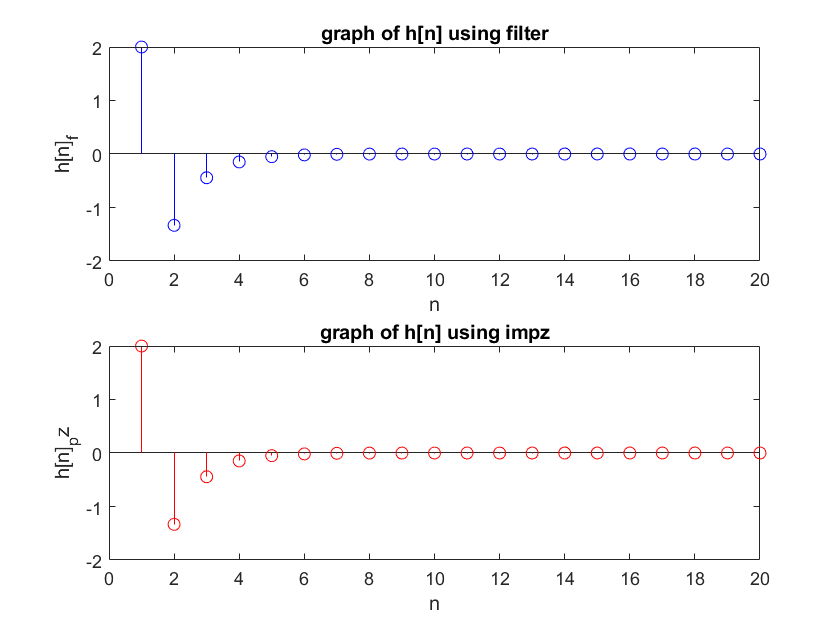

del = zeros(1,20); del(1)=1; % create delta[n] with 20 samples
% use filter
hn_f = filter(b,a,del); % y[n] = x[n]*h[n] let x[n]=delta[n] then y[n]=h[n] 
% use impz
hn_pz=impz(b,a,20); % 20 --> 20 samples 

% plot and compare
figure;
subplot(2,1,1);
stem(hn_f,'b');
title('graph of h[n] using filter'); xlabel('n'); ylabel('h[n]_f');


subplot(2,1,2); 
stem(hn_pz,'r');
title('graph of h[n] using impz'); xlabel('n'); ylabel('h[n]_pz');


same_hn = length(hn_pz==hn_f'); % length = 20 (all the same for 20 samples)

 As we can see , two method get totally same results (由圖形或是最後的same_hn) 

(d)

[r,p,c]=residuez(b,a); %  r=-4 p=-0.3333=-1/3 c=6

After knowing **r=-4 p=1/3 c=6** , we can rebuild H(Z) = $c+\frac{r}{1-{\mathrm{pz}}^{-1} }$ , which is equal to $6+\frac{-4}{1-\frac{1}{3}z^{-1} }$  . Now apply z-transform pairs in the Table3.1 and finally we  get 

h[n]=6$\delta \left\lbrack n\right\rbrack$$-4{\left(\frac{1}{3}\right)}^n u\left\lbrack n\right\rbrack$  , again .

clear all;

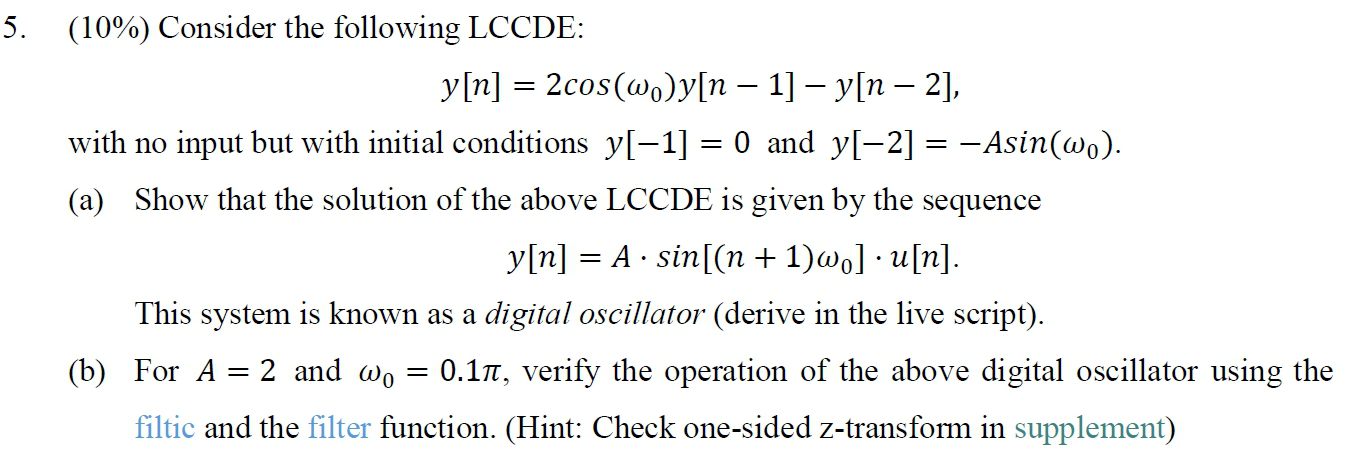

Note : no input means no x[n] (or **x[n]=0 for all n**)

(a) Accroding to the formula provided in the supplement  : 

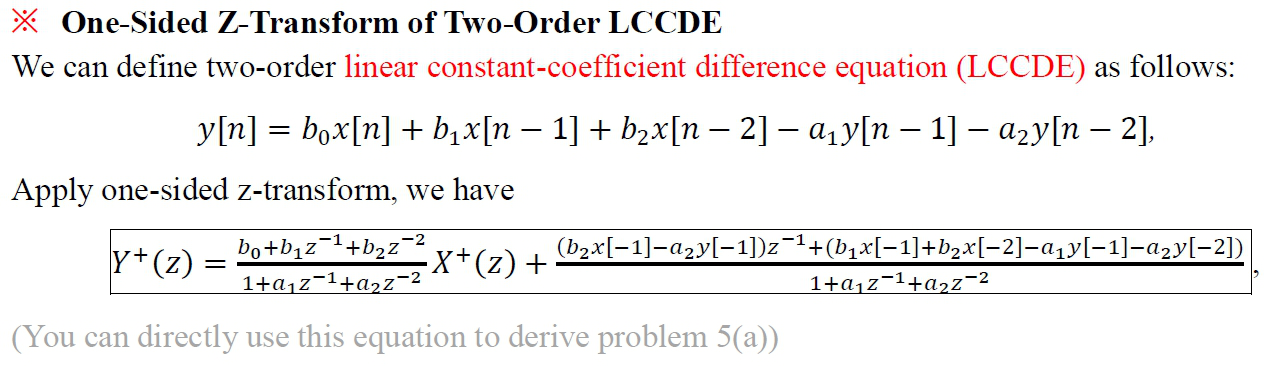

with ${\mathit{\mathbf{b}}}_0 ={\mathit{\mathbf{b}}}_1 ={\;\mathit{\mathbf{b}}}_2 =0$ $\mathrm{and}\;a_1 =-2\mathrm{cos}\left(\omega_0 \right),{\;a}_2 =1,\;y\left\lbrack -1\right\rbrack =0,y\left\lbrack -2\right\rbrack =-\mathrm{Asin}\left(\omega_0 \right)$ ,  we have 

$Y^+ \left(z\right)=0+\frac{\mathrm{Asin}\left(\omega_0 \right)}{1-2\mathrm{cos}\left(\omega_0 \right)z^{-1} +z^{-2} }$ = $\frac{\mathrm{Asin}\left(\omega_0 \right)}{1-2\mathrm{cos}\left(\omega_0 \right)z^{-1} +z^{-2} }$  (eq1)

 Now again using Table 3.1 :


$$\;\mathrm{property}\;8\;:\;x\left\lbrack n\right\rbrack =\mathrm{sin}\left(\omega_0 n\right)u\left\lbrack n\right\rbrack \longleftarrow z\;\mathrm{transform}\longrightarrow X\left(z\right)=\frac{\mathrm{sin}\left(\omega_0 \right)z^{-1} }{1-2\mathrm{cos}\left(\omega_0 \right)z^{-1} +z^{-2} }$$



$$\begin{array}{l}
\;\mathrm{time}\;\mathrm{shift}\;\mathrm{property}\;\left(\mathrm{left}\;\mathrm{shift}\;\mathrm{one}\;\mathrm{sample}\right):\;x\left\lbrack n+1\right\rbrack =\mathrm{sin}\left(\omega_0 \left(n+1\right)\right)u\left\lbrack n+1\right\rbrack \longleftarrow z\;\mathrm{transform}\longrightarrow X\left(z\right)\\
=\frac{z\cdot \mathrm{sin}\left(\omega_0 \right)z^{-1} }{1-2\mathrm{cos}\left(\omega_0 \right)z^{-1} +z^{-2} }=\frac{\mathrm{sin}\left(\omega_0 \right)}{1-2\mathrm{cos}\left(\omega_0 \right)z^{-1} +z^{-2} }\;\;\left(\mathrm{eq2}\right)\;\;\ldotp \;\mathrm{Apparently}\;\mathrm{eq1}\;=A\cdot \mathrm{eq2}
\end{array}$$
  

Thus , $y\left\lbrack n\right\rbrack =A\cdot \mathrm{sin}\left\lbrack \omega_0 \left(n+1\right)\right\rbrack u\left\lbrack n+1\right\rbrack$ = $A\cdot \mathrm{sin}\left\lbrack \omega_0 \left(n+1\right)\right\rbrack u\left\lbrack n\right\rbrack$ .  (Since for n= -1 $y\left\lbrack -1\right\rbrack =A\cdot \mathrm{sin}\left\lbrack \omega_0 \left(0\right)\right\rbrack u\left\lbrack 0\right\rbrack$) = 0 )

(b)  For $A=2,{\;\omega }_0 =0\ldotp 1\pi$ and with the help of the reference code :

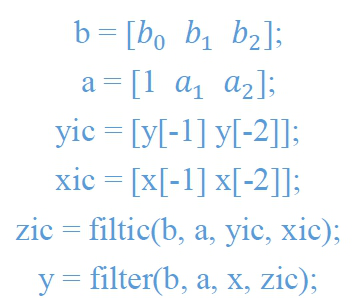

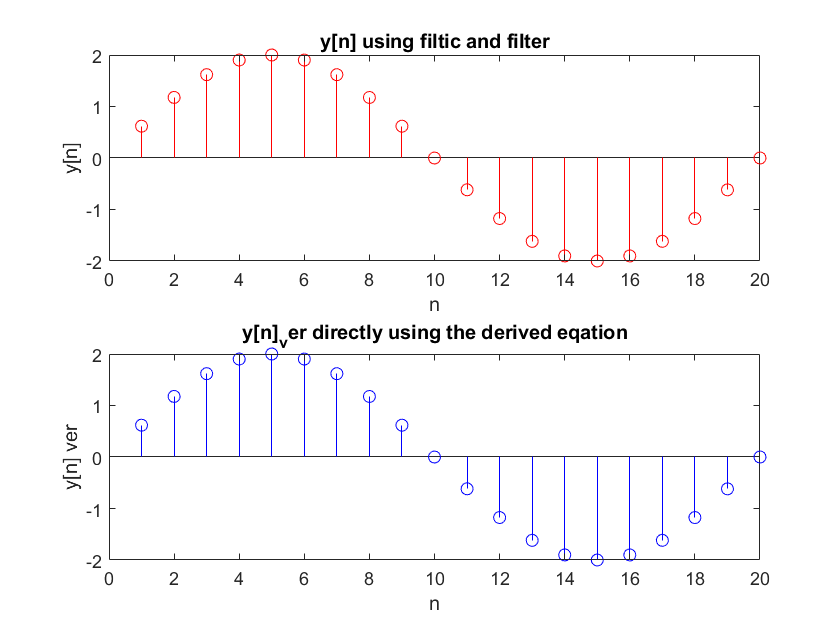

% insert the values from part (a)
b = [0 0 0]; 
a= [1 -2*cos(0.1*pi) 1]; 
yic = [0 -2*sin(0.1*pi)]; 
xic = [0 0]; % no inputs
zic = filtic(b,a,yic,xic); 
yn = filter(b,a,zeros(1,20),zic); % zeros(1,20) --> 20 samples , with no input

n = 0:19; yn_ver = 2*sin(0.1*pi*(n+1)); %  for vertifing if the above operation is right

figure;
subplot(2,1,1);
stem(yn,'r');
title('y[n] using filtic and filter'); xlabel('n'); ylabel('y[n]');
subplot(2,1,2);
stem(yn_ver,'b');
title('y[n]_ver directly using the derived eqation'); xlabel('n'); ylabel('y[n] ver');

由兩張圖形(計算得到的yn_ver與使用filtic filter得到的yn)有相同結果可以知道，filtic filter確實能夠

用來計算one-sided Z transform 並得到正確的結果

clear all;

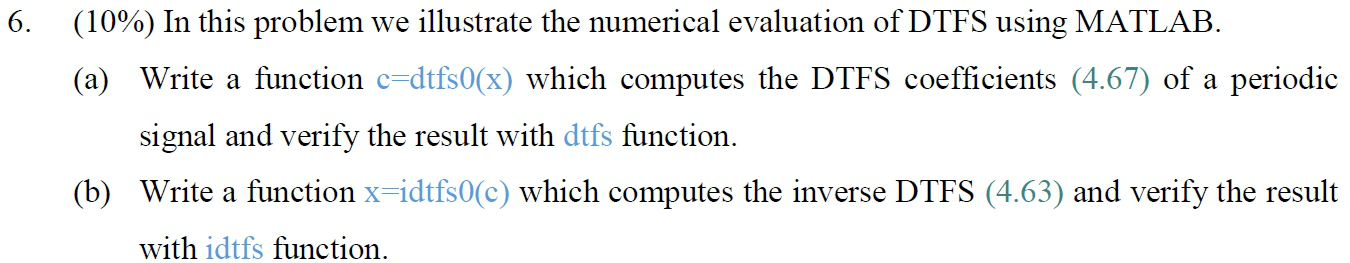

(a) test the written function 'dtfs0'  and compare it with the 'dtfs' funtion

test_x = [1 0 1 1 0 0 1];
c1 = dtfs0(test_x);
c2 = dtfs(test_x);
same_dtfs = length(round(c1,4) == round(c2,4)) ; % length = 7 (all the same)

(b) test the written function 'idtfs0'  and compare it with the 'idtfs' funtion

test_c = [1 -3 1 0 2 ];
x1 = idtfs0(test_c);
x2 = idtfs(test_c);
same_idtfs = length(round(x1,4) == round(x2,4)) ; % length = 5 (all the same)

As we can see , the written fuction (dtfs0 idtfs0) works well compared with the given ones  (dtfs idtfs)  [小數點後4位以前都是相同的)][若是看到後32位可能有些許不同、但差異仍舊不大]

clear all;

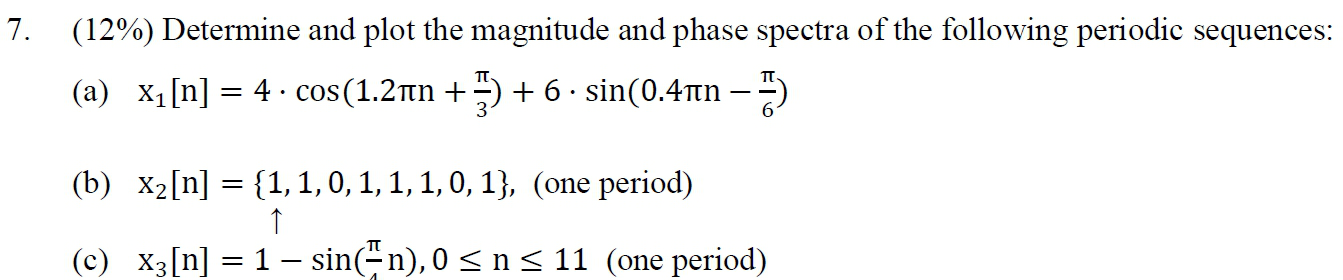

Note : 由於是periodic sequence , 因此使用**DTFS**來進行轉換

另外我將轉換後的k = 0 : N-1 變換成** f** = $\frac{k}{N}$ = 0 : $\frac{N-1}{N}$  意即 magnitude、phase的x軸皆以

**cycles / samples**的**頻率**表示。且在顯示**phase的y軸**時我使用** radian** (範圍: $-\pi ~+\pi$)表示

(a) apparently N= 5 for one period , so n = 0~4

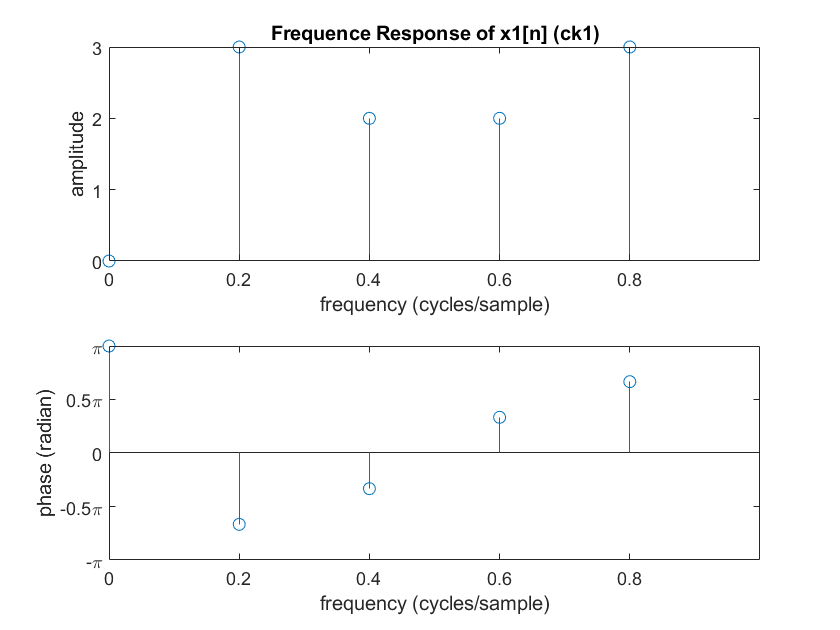

n1 = 0:4; xn1 = 4*cos(1.2*pi*n1+1/3*pi)+6*sin(0.4*pi*n1-1/6*pi); % create x1[n]
c1=dtfs0(xn1); space1=n1/5; % apply dtfs and set the space

figure;
subplot(2,1,1);
stem(space1,abs(c1)); % magnitude
title('Frequence Response of x1[n] (ck1)');
xlabel('frequency (cycles/sample)'); xlim([0 1]); % set x axis to f=0~1
set(gca,'XTick',space1);
ylabel('amplitude');

subplot(2,1,2);
stem(n1/5, angle(c1)/pi); % phase
xlabel('frequency (cycles/sample)'); xlim([0 1]); % set x axis to f=0~1
set(gca,'XTick',space1);
ylabel('phase (radian)');
yticklabels({'-\pi','-0.5\pi','0','0.5\pi','\pi'});

(b)

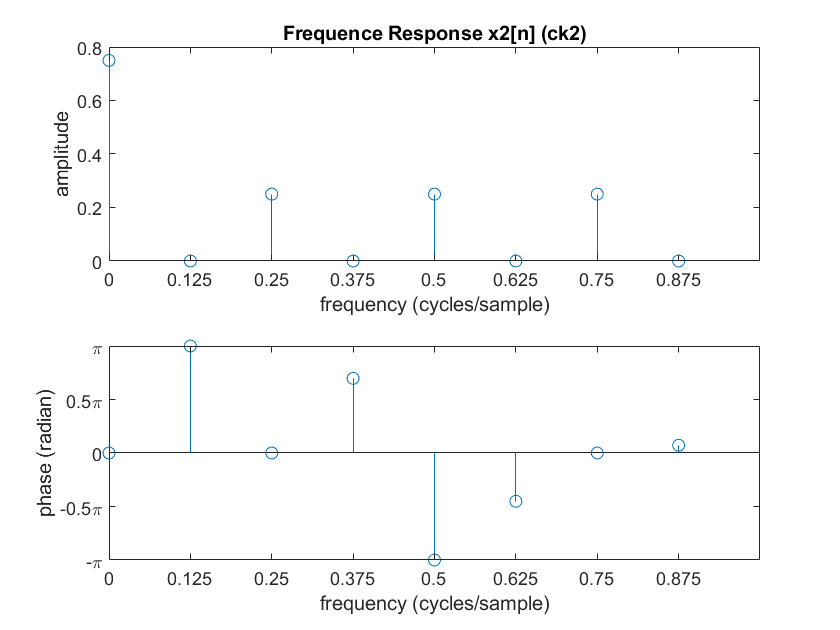

xn2 = [1 1 0 1 1 1 0 1]; % create x2[n]
c2=dtfs0(xn2); space2=(0:7)/8; % apply dtfs and set the space

figure;
subplot(2,1,1);
stem(space2,abs(c2)); % magnitude
title('Frequence Response x2[n] (ck2)');
xlabel('frequency (cycles/sample)'); xlim([0 1]); % set x axis to f=0~1
set(gca,'XTick',space2);
ylabel('amplitude');

subplot(2,1,2);
stem((0:7)/8, angle(c2)/pi); % phase
xlabel('frequency (cycles/sample)'); xlim([0 1]); % set x axis to f=0~1
set(gca,'XTick',space2);
ylabel('phase (radian)');
yticklabels({'-\pi','-0.5\pi','0','0.5\pi','\pi'});

(c)

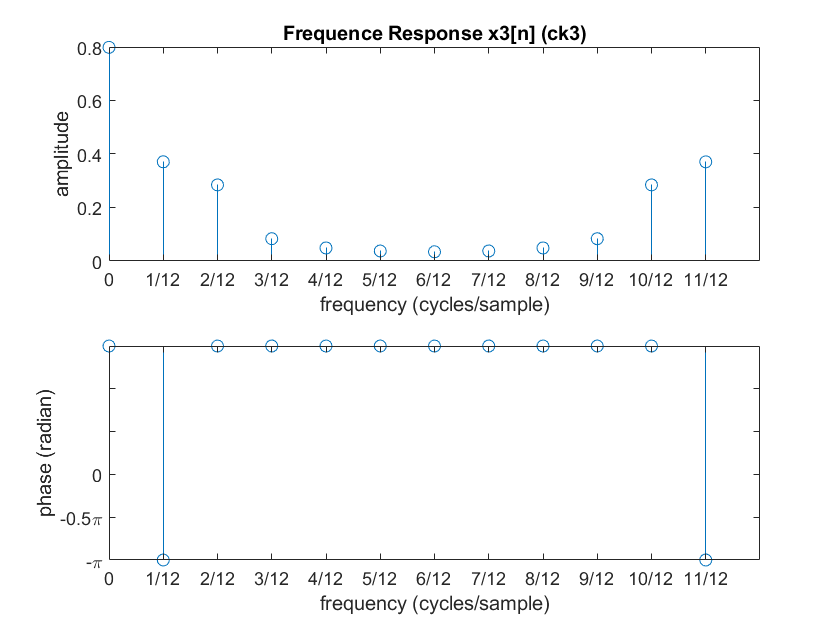

n3 = 0:11; xn3 =1-sin(0.25*pi*n3);  % create x3[n]
c3=dtfs0(xn3);  space3=n3/12; % apply dtfs and set the space

figure;
subplot(2,1,1);
stem(space3,abs(c3)); % magnitude
title('Frequence Response x3[n] (ck3)');
xlabel('frequency (cycles/sample)'); xlim([0 1]); % set x axis to f=0~1
set(gca,'XTick',space3); 
xticklabels({'0','1/12','2/12','3/12','4/12','5/12','6/12','7/12','8/12','9/12','10/12','11/12'});
ylabel('amplitude');

subplot(2,1,2);
stem(n3/12, angle(c3)/pi); % phase
xlabel('frequency (cycles/sample)'); xlim([0 1]); % set x axis to f=0~1
set(gca,'XTick',space3);
xticklabels({'0','1/12','2/12','3/12','4/12','5/12','6/12','7/12','8/12','9/12','10/12','11/12'});
ylabel('phase (radian)');
yticklabels({'-\pi','-0.5\pi','0'});

為了讓顯示出的圖形較易理解，我更改了部分x軸、y軸的label間距以及顯示單位

clear all;

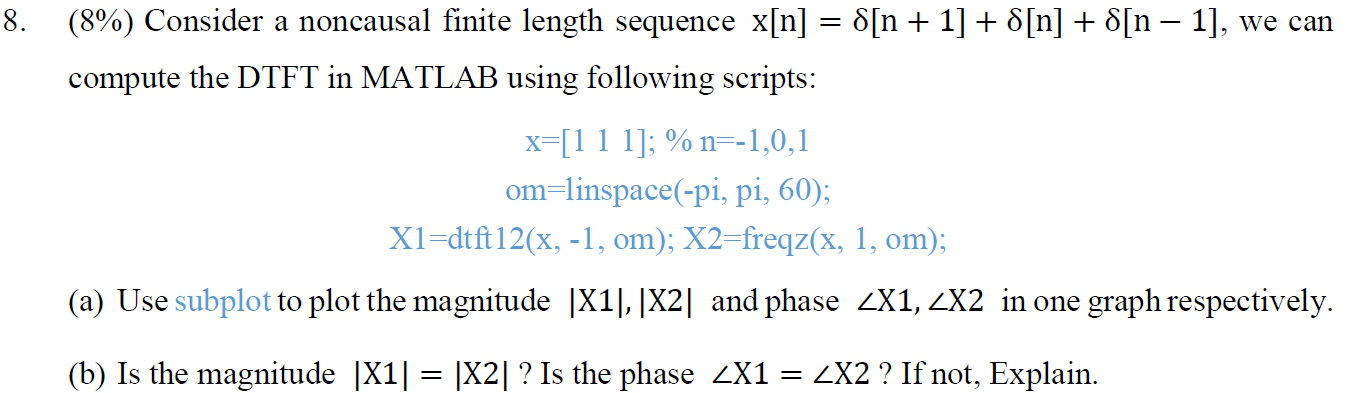

x=[1 1 1]; % n=-1,0,1 
om=linspace(-pi, pi, 60);
X1=dtft12(x, -1, om); X2=freqz(x, 1, om); 

(a)

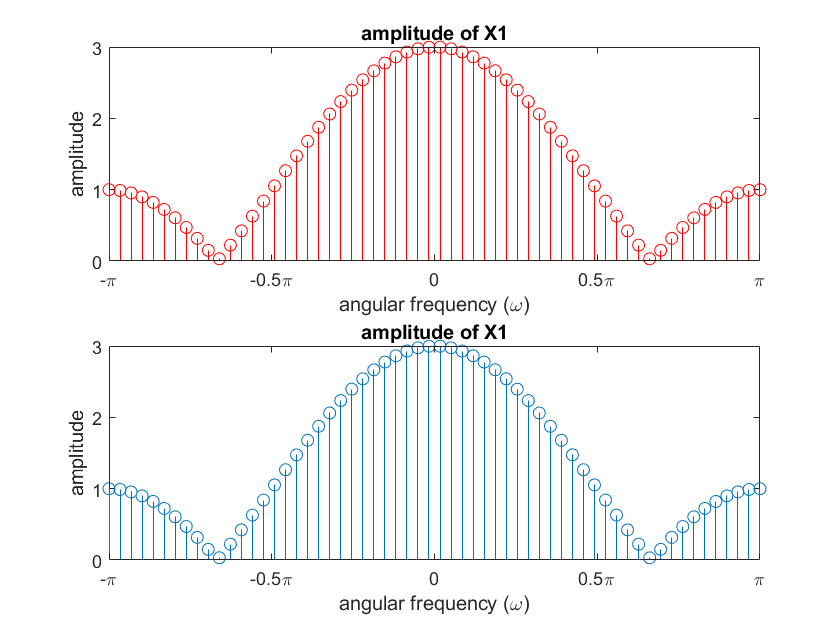

figure; % amplitude

subplot(2,1,1);
stem(om/pi,abs(X1),'r');
title('amplitude of X1');
xlabel('angular frequency (\omega)');
set(gca,'XTick',-1:0.5:1);
xticklabels({'-\pi','-0.5\pi','0','0.5\pi','\pi'});
ylabel('amplitude');


subplot(2,1,2);
stem(om/pi,abs(X2));
title('amplitude of X1');
xlabel('angular frequency (\omega)');
set(gca,'XTick',-1:0.5:1);
xticklabels({'-\pi','-0.5\pi','0','0.5\pi','\pi'});
ylabel('amplitude');

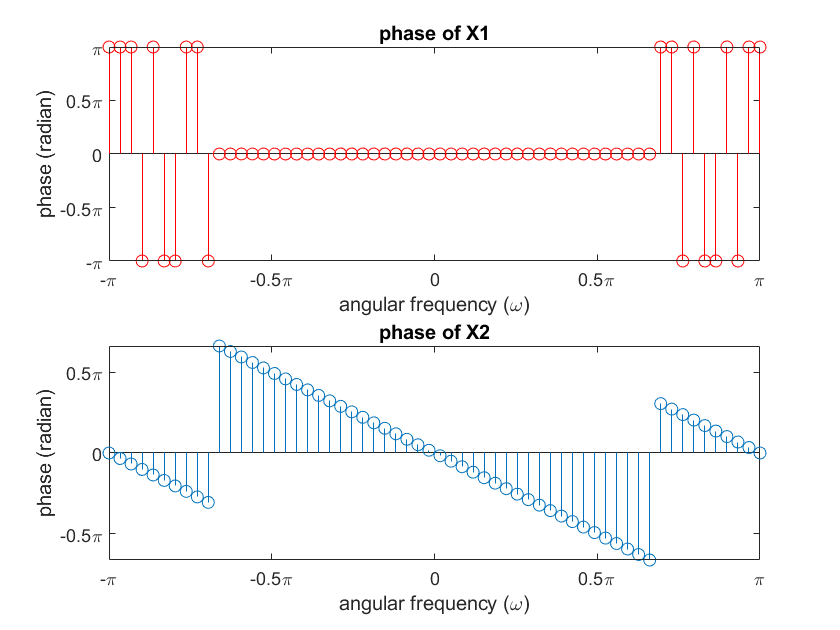

figure; % phase

subplot(2,1,1);
stem(om/pi, angle(X1)/pi,'r');
title('phase of X1');
xlabel('angular frequency (\omega)');
set(gca,'XTick',-1:0.5:1);
xticklabels({'-\pi','-0.5\pi','0','0.5\pi','\pi'});
ylabel('phase (radian)');
yticklabels({'-\pi','-0.5\pi','0','0.5\pi','\pi'});


subplot(2,1,2);
stem(om/pi, angle(X2)/pi);
title('phase of X2');
xlabel('angular frequency (\omega)');
set(gca,'XTick',-1:0.5:1);
xticklabels({'-\pi','-0.5\pi','0','0.5\pi','\pi'});
ylabel('phase (radian)');
yticklabels({'-0.5\pi','0','0.5\pi'});

(b)

兩種方法(dtft12、freqz)得到的magnitude相同但是phase不同，造成phase 不同的原因如下 :

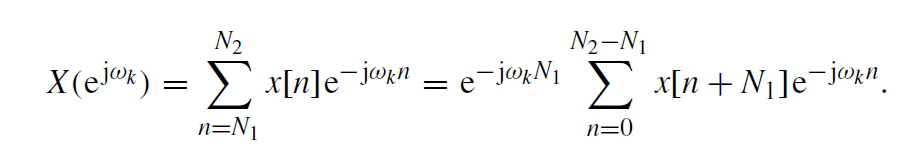

由於freqz永遠假設N1 = 0 ，意即 freqz計算的是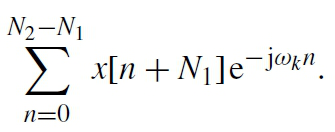這項，而

dtft計算的才是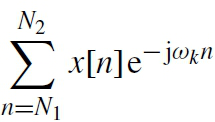這項，因此兩者之間有一項phase shift 

(不影響amplitude) 才會造成得到的phase 不同 .

Note: 也需要注意matlab在使用actan function時不一定會得到其位置需要的$\pm \pi$

因此需要使用者透過real signal的FT phase有odd symmetry來做適當的選擇.

clear all;

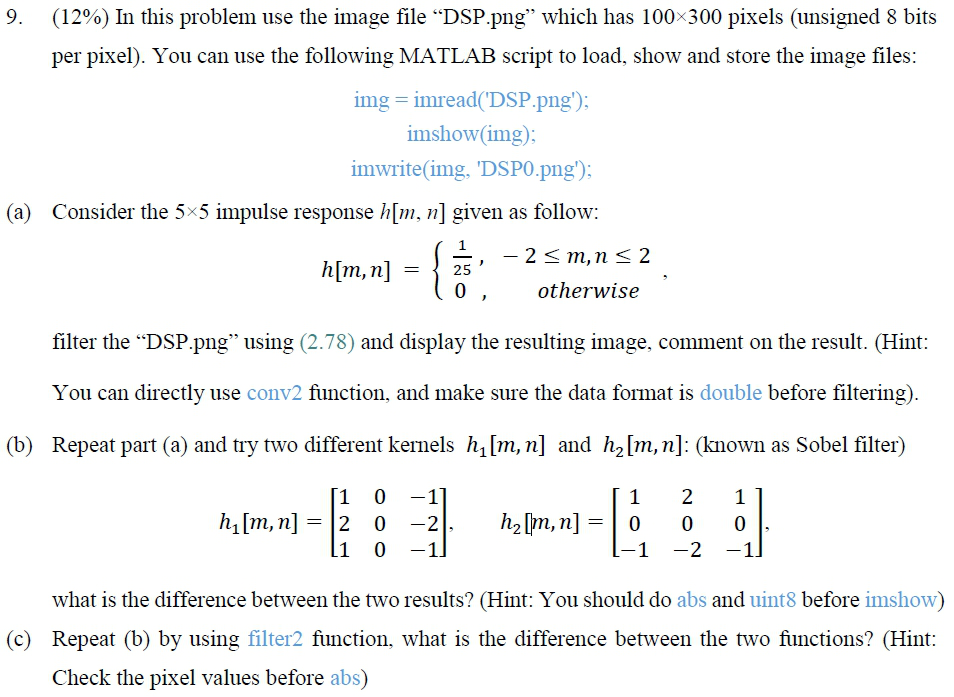

(a)

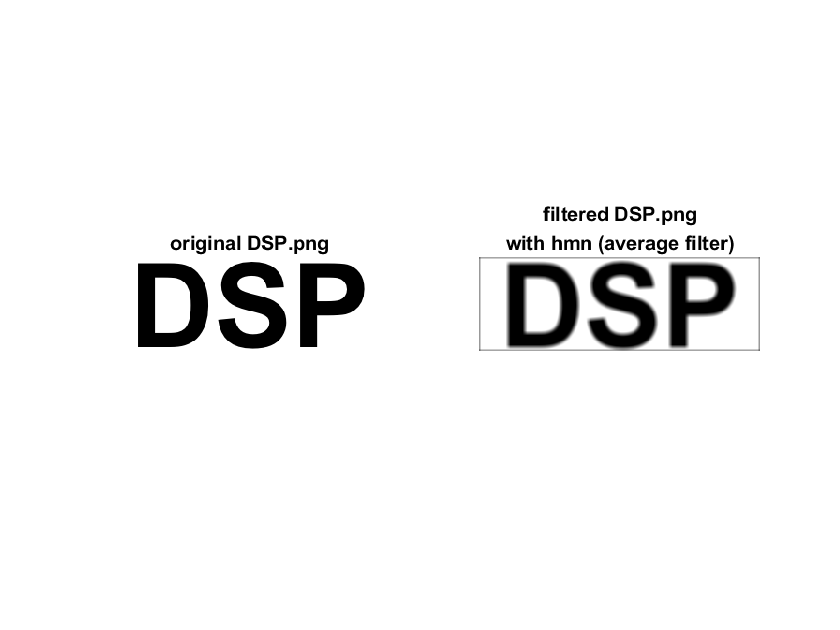

img = imread('DSP.png');

hmn = 1/25 * ones(5,5); % average matrix 
img_dou = double(img);
img_hmn = conv2(img_dou,hmn,'same'); % average filter the image

figure;
subplot(1,2,1);
imshow(img);
title('original DSP.png');
subplot(1,2,2);
imshow(uint8(abs(img_hmn)));
title({'filtered DSP.png','with hmn (average filter)'});

由於使用得是average filter，因此將'DSP.png'與此filter 做 convolution之後

得到的新照片'filtered DSP.png'上的各點(pixel)會是原照片此點附近值的平均

這會造成原本有劇烈改變的點在filter後改變幅度變小，意即照片的邊界(boundary)

會變得模糊(blur)、或者說平滑(smooth). 觀察得到的照片的確可以看到這樣的結果.

(b)

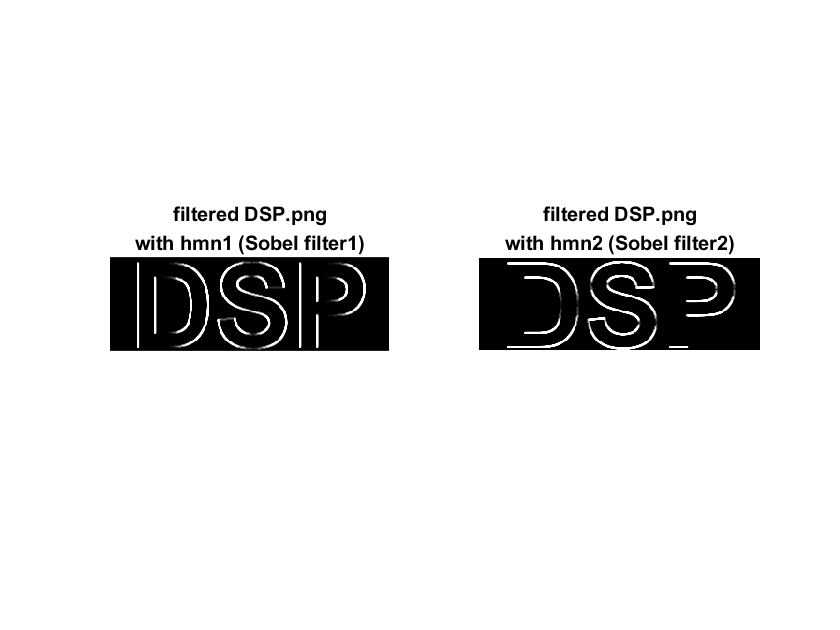

hmn1 = [1 0 -1;2 0 -2;1 0 -1]; 
hmn2 = [1 2 1;0 0 0;-1 -2 -1]; 

img_hmn1 = conv2(img_dou,hmn1,'same');
img_hmn2 = conv2(img_dou,hmn2,'same');



figure;
subplot(1,2,1);
imshow(uint8(abs(img_hmn1))); % vertical 
title({'filtered DSP.png','with hmn1 (Sobel filter1)'});
subplot(1,2,2);
imshow(uint8(abs(img_hmn2))); % horizontal
title({'filtered DSP.png','with hmn2 (Sobel filter2)'});

  Sobel filter 主要用來檢測x、y方向的梯度(即單位變化量) , 

  觀察hmn1可以發現其應是偵測y方向梯度，因此顯示出的照片'img_hmn1'上可以看到

  DSP三個字在垂直方向上有明顯亮線(垂直梯度變化) (S應該是因為不是單純的x或y方向梯 

  度所以幾乎都是亮線、只有最頂端和底端是完全水平所以是暗的(0垂直梯度))

  同理，hmn2是偵測x方向梯度，因此顯示出的照片'img_hmn2'亦可看到DSP在水平方

  向上有明顯亮線(水平梯度變化)且同樣的S只有少數部分是暗線(0水平梯度)

(c)

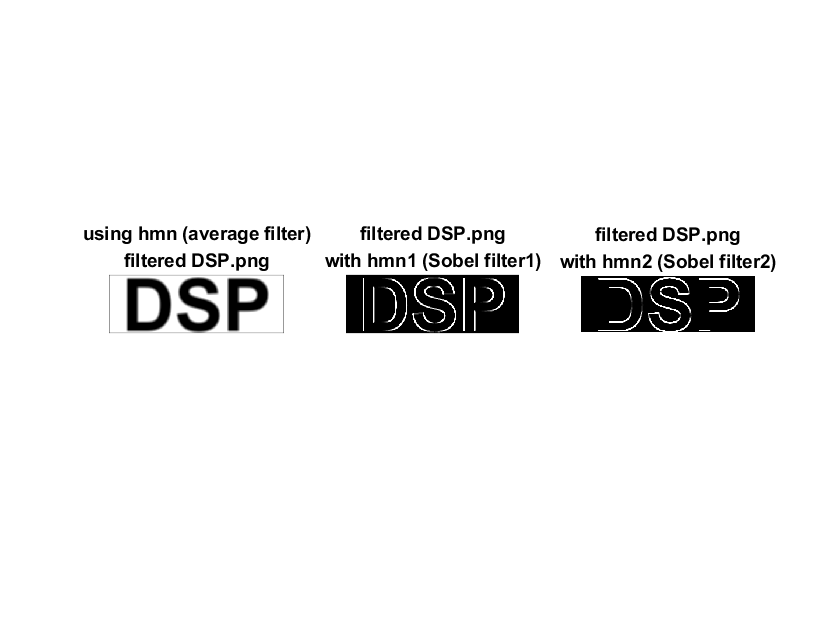

img_filter_hmn = filter2(hmn,img_dou);
img_filter_hmn1 = filter2(hmn1,img_dou);
img_filter_hmn2 = filter2(hmn2,img_dou);


figure;
subplot(1,3,1);
imshow(uint8(abs(img_filter_hmn)));
title({'using hmn (average filter)','filtered DSP.png'});
subplot(1,3,2);
imshow(uint8(abs(img_filter_hmn1)));
title({'filtered DSP.png','with hmn1 (Sobel filter1)'});
subplot(1,3,3);
imshow(uint8(abs(img_filter_hmn2)));
title({'filtered DSP.png','with hmn2 (Sobel filter2)'});


% filter2(h,x,shape) 等同于 conv2(x,rot90(h,2),shape)

將(b)的部分用filter2 repeat得到的照片顯示出來，乍看之下似乎與(a)、(b)部分

用conv2做得結果相同，但若是檢查取abs()前的各matrix便可以發現兩種fuction

(conv2、filter2)的不同.  

實際上 conv2做的是2D convolution , 因此hmn會先經過x、y方向各一次的反轉(flip)

(或是旋轉180度)  在與input做inner product sum (2矩陣重疊部分取內積之和) 

而filter2做的是2D corelation ,  因此hmn直接與input做inner product sum(未經旋轉)

意即 :  filter2(h,x,shape) 等同于 conv2(x,rot90(h,2),shape) 

另外，由於hmn完全對稱而hmn1、hmn2各自具有1個方向上的對稱性，

因此將hmn選轉180度後沒有任何改變

將hmn1 hmn2選轉180度後只會造成正負號相反，固得到的結果

img_hmn1=完全相同(img_filter_hmn) 

img_hmn1=正負號相反(img_filter_hmn) 

img_hmn2=正負號相反(img_filter_hmn2) 

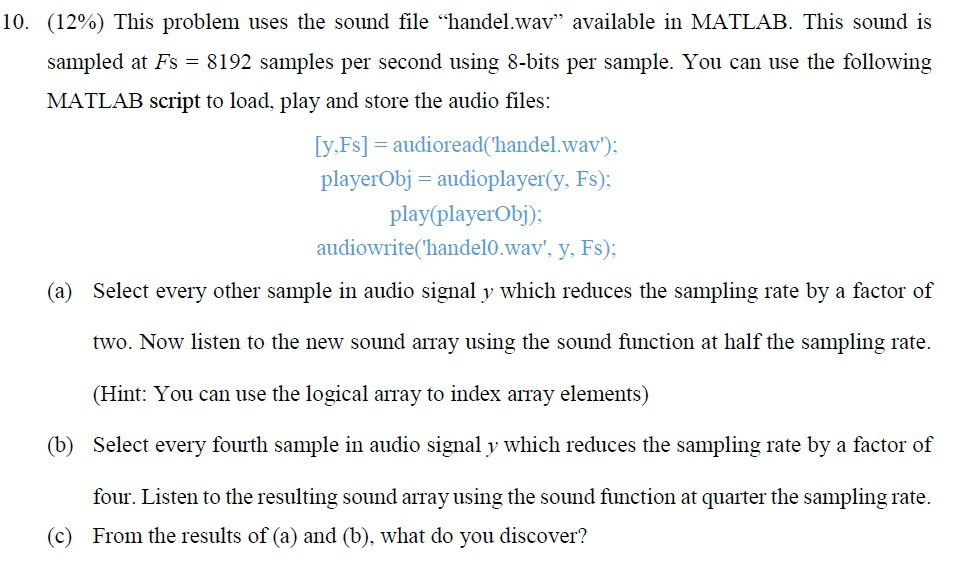

[y,Fs] = audioread('handel.wav');
playerObj = audioplayer(y, Fs);
play(playerObj);

y_down2 = downsample(y,2);
y_down4 = downsample(y,4);
playerObj1 = audioplayer(y_down2, Fs/2);
play(playerObj1);
playerObj2 = audioplayer(y_down4, Fs/4);
play(playerObj2);